% --- Parameters ---
R = 0.02;          % Rotor magnet radius [m]
alpha = 1.2e-7;    % Lift scaling coefficient
n = 2.5;           % Air-gap power-law exponent
beta = 0.005;      % Low-speed eddy-current buildup rate [s/rad]
c_z = 0.02;        % Vertical damping coefficient [N*s/m]
z0 = 0.002;        % Nominal center height above floor [m]
area = pi * R^2;
tilt_sq = 0.0;                      % theta^2 + phi^2 [rad^2]

m = 0.05;          % Effective mass per lifter [kg]
g = 9.81;          % Gravity [m/s^2]

% Find an equilibrium from angular rate
w_eq = 50*2*pi;    % Operating angular rate [rad/s]
target_Fz = m * g; % Equilibrium lift required [N]

eq_res = @(z_cand) ...
    (area * alpha * (w_eq^2) / (z_cand^n) * (1 - exp(-beta * w_eq))) * ...
    (1 + (n * (n + 1) / 8) * ((R / z_cand)^2) * tilt_sq) - target_Fz;
% Operating center height [m]
if tilt_sq == 0
    Fz0_coeff = area * alpha * (w_eq^2) * (1 - exp(-beta * w_eq));
    z_eq = (Fz0_coeff / target_Fz)^(1 / n);
else
    z_eq = fzero(eq_res, [1e-4, 1.0]);
end

% --- Linearization Around Operating Point (z_eq, w_eq) ---
Fz0_eq = area * alpha * (w_eq^2) / (z_eq^n) * (1 - exp(-beta * w_eq));
tilt_factor_eq = 1 + (n * (n + 1) / 8) * ((R / z_eq)^2) * tilt_sq;
Fz_net_eq = Fz0_eq * tilt_factor_eq;

dFz_dz = -(n / z_eq) * Fz_net_eq - (2 / z_eq) * Fz0_eq * (tilt_factor_eq - 1);
dFz0_dw = area * alpha * (z_eq^(-n)) * ...
    (2 * w_eq * (1 - exp(-beta * w_eq)) + beta * (w_eq^2) * exp(-beta * w_eq));
dFz_dw = dFz0_dw * tilt_factor_eq;

A = [0, 1;
     dFz_dz / m, -c_z / m];

B = [0;
     dFz_dw / m];

C = eye(2);        % Output both states [z; z_dot]
D = [z_eq; 0];

rotor_model = ss(A, B, C, D, ...
    'StateName', {'z', 'z_dot'}, ...
    'InputName', {'w'}, ...
    'OutputName', {'z', 'z_dot'});

% --- Linearized Model Diagnostics ---
eigValues = eig(A);
fprintf('Equilibrium point: %.4f rad/s, height: %.8f m\n', w_eq, z_eq);

Equilibrium point: 314.1593 rad/s, height: 0.01420160 m


fprintf('Equilibrium lift: %.4f N (weight: %.4f N)\n', Fz_net_eq, m * g);

Equilibrium lift: 0.4905 N (weight: 0.4905 N)


fprintf('Linearized poles: %.4f%+.4fi, %.4f%+.4fi\n', ...
    real(eigValues(1)), imag(eigValues(1)), real(eigValues(2)), imag(eigValues(2)));

Linearized poles: -0.2000+41.5557i, -0.2000-41.5557i


set(groot, ...
    'defaultFigureColor', [1 1 1], ...
    'defaultAxesColor', [1 1 1], ...
    'defaultAxesXColor', [0 0 0], ...
    'defaultAxesYColor', [0 0 0], ...
    'defaultAxesZColor', [0 0 0], ...
    'defaultAxesGridColor', [0.15 0.15 0.15], ...
    'defaultAxesGridAlpha', 0.25, ...
    'defaultTextColor', [0 0 0]);

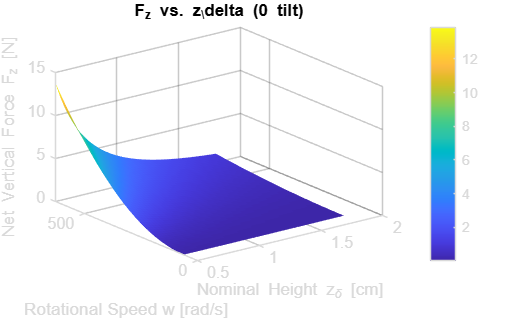

% --- z and w Sweep Ranges ---
z_delta_vec = linspace(0.005, 0.02-z0, 50);  % Change in center height [m]
w_vec = linspace(10*2*pi, 100*2*pi, 50);   % Angular rate [rad/s]
tilt_sq = 0.0;                      % theta^2 + phi^2 [rad^2]

[z_delta, w] = meshgrid(z_delta_vec, w_vec);
z = z_delta + z0;                        % Actual center height z [m]

% --- Lift Calc ---
Fz0 = area * alpha .* (w.^2) ./ (z.^n) .* (1 - exp(-beta * w));
tilt_factor = 1 + (n * (n + 1) / 8) * ((R ./ z).^2) * tilt_sq;
Fz_net = Fz0 .* tilt_factor;

% --- Plot ---
figure('Color', 'w');
surf(z_delta * 100, w, Fz_net, 'EdgeColor', 'none');
colorbar;
xlabel('Nominal Height z_\delta [cm]');
ylabel('Rotational Speed w [rad/s]');
zlabel('Net Vertical Force F_z [N]');
title('F_z vs. z_\\delta (0 tilt)');
grid on;

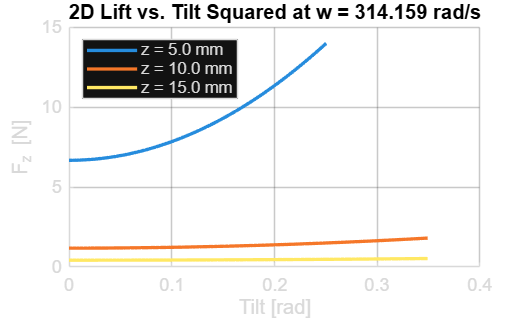

% --- Tilt Sweep ---
w_fixed = 50*2*pi;                      % Fixed angular speed [rad/s]
z_list = [0.005, 0.010, 0.015];    % Nominal gaps z_delta [m] to compare
tilt_vec = linspace(0, deg2rad(20), 100); % Sweep of (theta^2 + phi^2)^0.5 [rad]
tilt_sq_vec = tilt_vec.^2;              

figure('Color', 'w');
hold on;
grid on;

for idx = 1:length(z_list)
    z_val = z_list(idx);

    % Mask out angles where lowest rim point (R * sin(tilt)) reaches/exceeds ground clearance
    valid_mask = (R * sin(tilt_vec)) < z_val;
    tilt_valid = tilt_vec(valid_mask);
    tilt_sq_valid = tilt_sq_vec(valid_mask);
    
    Fz0_val = area * alpha * (w_fixed^2) / (z_val^n) * (1 - exp(-beta * w_fixed));
    tilt_factor = 1 + (n * (n + 1) / 8) * ((R / z_val)^2) * tilt_sq_valid;
    Fz_tilt = Fz0_val * tilt_factor;

    plot(tilt_valid, Fz_tilt, 'LineWidth', 2, ...
        'DisplayName', sprintf('z = %.1f mm', z_val * 1000));
end

xlabel('Tilt [rad]');
ylabel('F_z [N]');
title(sprintf('2D Lift vs. Tilt Squared at w = %g rad/s', w_fixed));
legend('Location', 'northwest');
set(gca, 'FontSize', 11);